Homework #03

## 1

1a)

[pic]

1b)

A=[-0.7108,-2.995;1.336,-0.7892];
x0 = [-5; 2];

% finding eigenvalues
a=A(1,1);
b=A(1,2);
c=A(2,1);
d=A(2,2);
disp('eigenvalues:')

eigenvalues:


lambda = [(a+d)/2+( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2), 0; ...
    0, (a+d)/2-( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2)];
lambda_vec = [lambda(1,1) lambda(2,2)]

lambda_vec =   -0.7500 + 1.9999i  -0.7500 - 1.9999i



% finding eigenvectors
e_vecs = zeros(length(lambda_vec), 2);
for i=1:1:length(lambda_vec)
    e_space = A-lambda_vec(1,i)*eye(2);
    e_vecs(:, i) = null(e_space);
end
disp('eigenvectors:')

eigenvectors:


disp(e_vecs)

   0.8316 + 0.0000i   0.8316 + 0.0000i
   0.0109 - 0.5553i   0.0109 + 0.5553i




% finding the a constant based on x0
disp('the a constant:')

the a constant:


a_const = e_vecs^(-1)*x0;
a_const=a_const.'

a_const =   -3.0063 + 1.8598i  -3.0063 - 1.8598i


1c)

t=2.0;

% diag turns elements of vector into diagonal elements
expm_A2=e_vecs*diag(exp(lambda_vec*t))*e_vecs^(-1)

expm_A2 =   -0.1492 + 0.0000i   0.2529 + 0.0000i
  -0.1128 - 0.0000i  -0.1426 + 0.0000i



disp('from Matlab expm() function:')

from Matlab expm() function:


disp(expm(A*t))

   -0.1492    0.2529
   -0.1128   -0.1426



The calculated sum is indeed equal to Matlab's expm output

disp('solution at t=2:')

solution at t=2:


disp(expm_A2*x0)

   1.2516 - 0.0000i
   0.2789 + 0.0000i



1d)

t=0:0.1:5;
x_traj=zeros(2,15);
for i=1:1:length(t)
    x_traj(:,i)=e_vecs*diag(exp(lambda_vec*t(1,i)))*e_vecs^(-1)*x0;
end

figure
hold on
[X,Y] = meshgrid(-10:1:10,-10:1:10);
X=X(:).';
Y=Y(:).';
gradient = A*[X;Y];
U = gradient(1,:);
V = gradient(2,:);

q = quiver(X,Y,U,V);

plot(x_traj(1,:), x_traj(2,:), 'm')

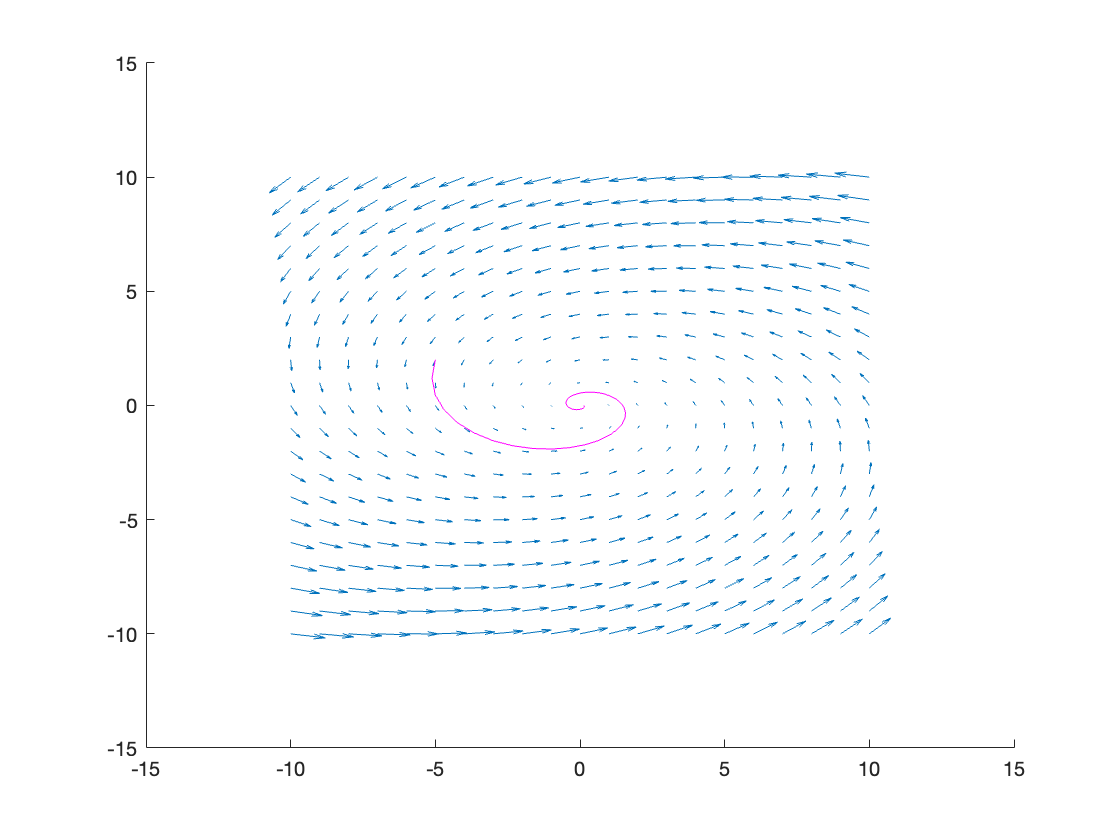

hold off

1e) So $\frac{dx}{dt}=ax+by$

then $\frac{d^2x}{dt^2}=a\frac{dx}{dt}+b\frac{dy}{dt}$

and if $\frac{dy}{dt}=cx+dy$

then $\frac{d^2x}{dt^2}=a\frac{dx}{dt}+b(cx+dy)$


$$=(aa +bc)x + (ab+bd)y$$


disp(['x''''=' num2str((a*a) + (b*c)) 'x+' num2str((a*b)+(b*d)) 'y'])

x''=-3.4961x+4.4925y


1fi)

t=2.0;
x2_sad=[-2; -2];

disp('initial conditions based on x2=[-2;-2]:')

initial conditions based on x2=[-2;-2]:


x0_sad=expm_A2^(-1)*x2_sad

x0_sad =   15.8843 - 0.0000i
   1.4615 - 0.0000i


1fii) 

For t=2, it is possible to optimize a starting condition point out on the trajectory that would lead to both positive values specifically at t=2.

However, long-term no, the eigenvalues have negative real parts:

disp(lambda_vec)

  -0.7500 + 1.9999i  -0.7500 - 1.9999i



So they will always eventually end up at 0, 0

1gi) 

t=0:0.1:15;
x_sad=zeros(2,15);
for i=1:1:length(t)
    x_sad(:,i)=e_vecs*diag(exp(lambda_vec*t(1,i)))*e_vecs^(-1)*x0_sad;
end

figure
hold on
plot(t, x_sad(1,:), 'r')

plot(t, x_sad(2,:), 'b')

plot(t, sqrt(x_sad(1,:).^2+x_sad(2,:).^2), 'g')

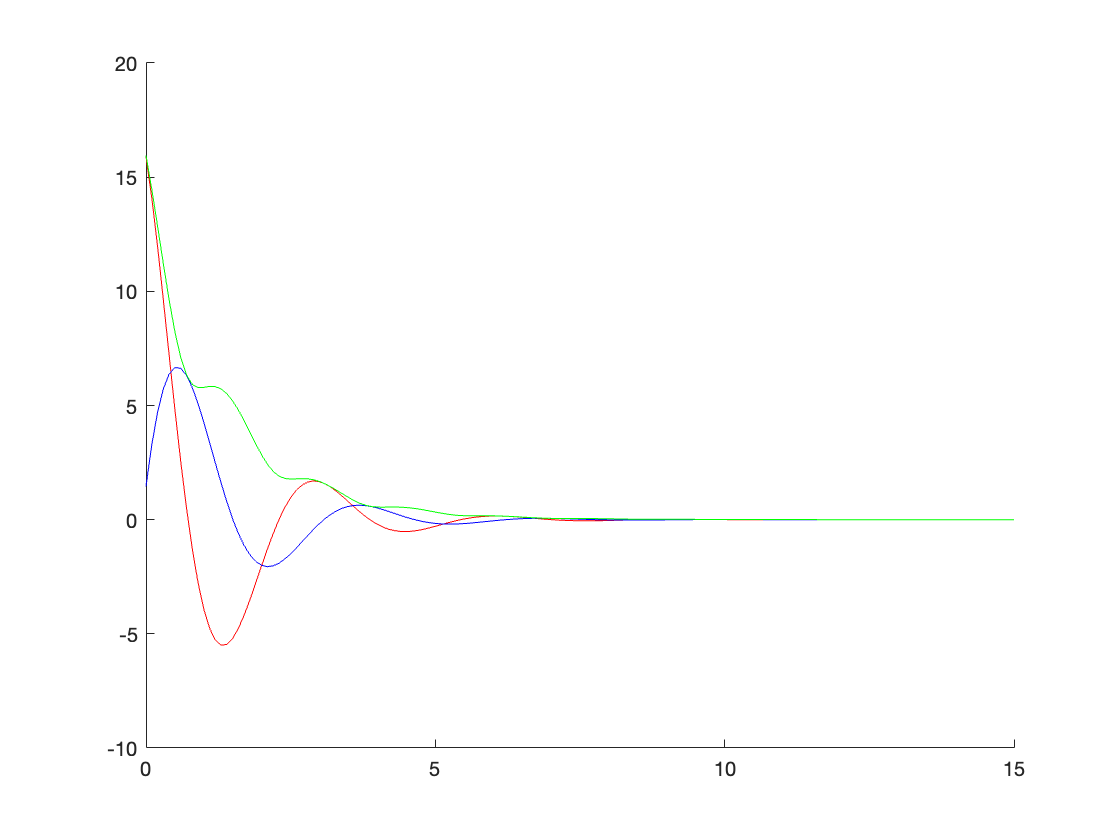

hold off

1gii)

figure
hold on
plot(x_sad(1,:), x_sad(2,:), 'm')

1giii)

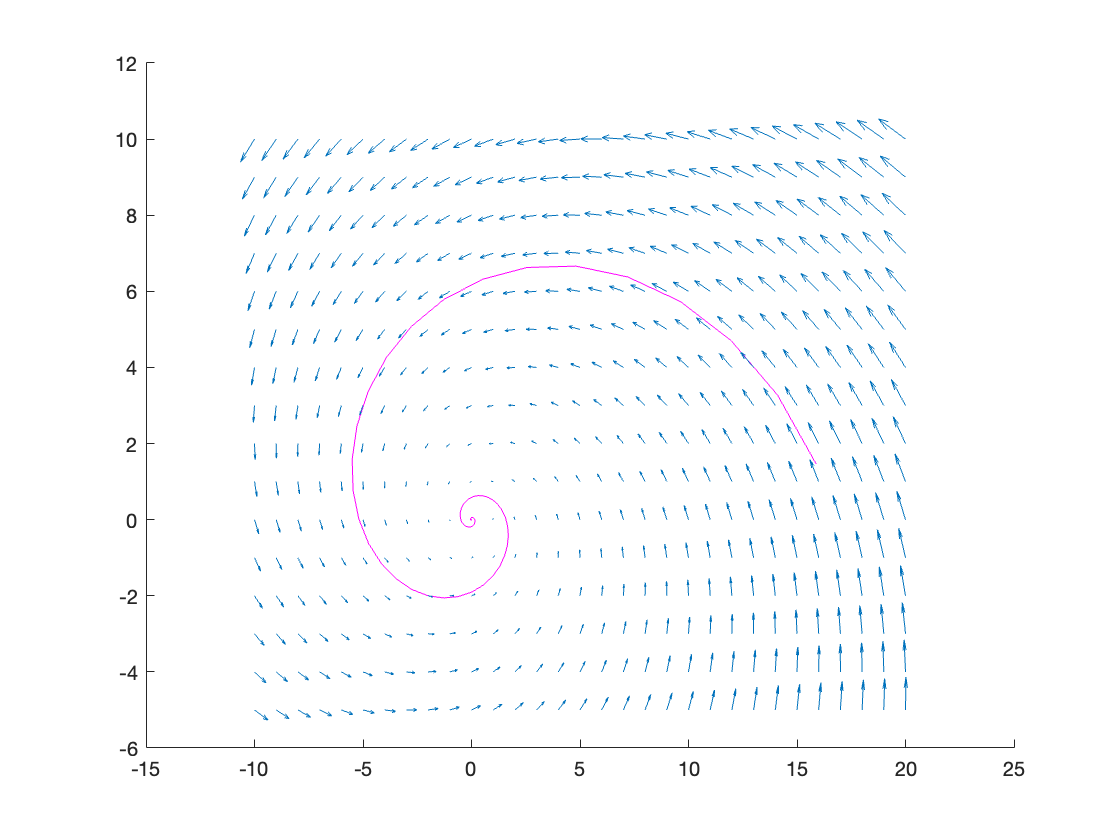

[X,Y] = meshgrid(-10:1:20,-5:1:10);
X=X(:).';
Y=Y(:).';
gradient = A*[X;Y];
U = gradient(1,:);
V = gradient(2,:);

q = quiver(X,Y,U,V);
hold off

## 2

2a)

A=[ -64.0859, -22.6535;
177.346, 62.6859];


TF during OH said I can use the eig() function directly here

[e_vecs, D]=eig(A);

disp('eigenvalues:')

eigenvalues:


lambda_vec = [D(1,1) D(2,2)]

lambda_vec =    -1.2145   -0.1855



disp('eigenvectors:')

eigenvectors:


disp(e_vecs)

   -0.3390    0.3341
    0.9408   -0.9425



Since $Ax=\sum_{i=1}^{n} c_i e_i e^{\lambda t}$  and the eigenvalues are negative, $e^{\lambda t}$ and $Ax$ overall will go towards 0. However, although they are both negative, one is much greater than the other.

Moreover, the two eigenvectors are also very close to each other and are therefore clearly linearly dependent on each other. Thus, there will also be some oscillation before it goes towards 0.

2b)

t=1.5;

% diag turns elements of vector into diagonal elements
B=e_vecs*diag(exp(lambda_vec*t))*e_vecs^(-1);
BT_B=B.'*B;

% eigenvector with max eigenvalue
v=BT_B^(50)*[1;1];
disp('initial condition for max amplitude:')

initial condition for max amplitude:


x0=v/norm(v)

x0 =     0.9403
    0.3403


disp('corresponding eigenvalue from B^T*B:')

corresponding eigenvalue from B^T*B:


amp_lambda = mean(BT_B*x0./x0)

amp_lambda = 1.3391e+04

Amplitude eigenvalue for maximizing sqrt(eigenvalue) is positive

2c)

% finding the a constant based on x0
disp('the a constant:')

the a constant:


a_const = inv(e_vecs)*x0;
a_const=a_const.'

a_const =  -194.3623 -194.3663


so writing it out explicitly:

[pic]

2d)

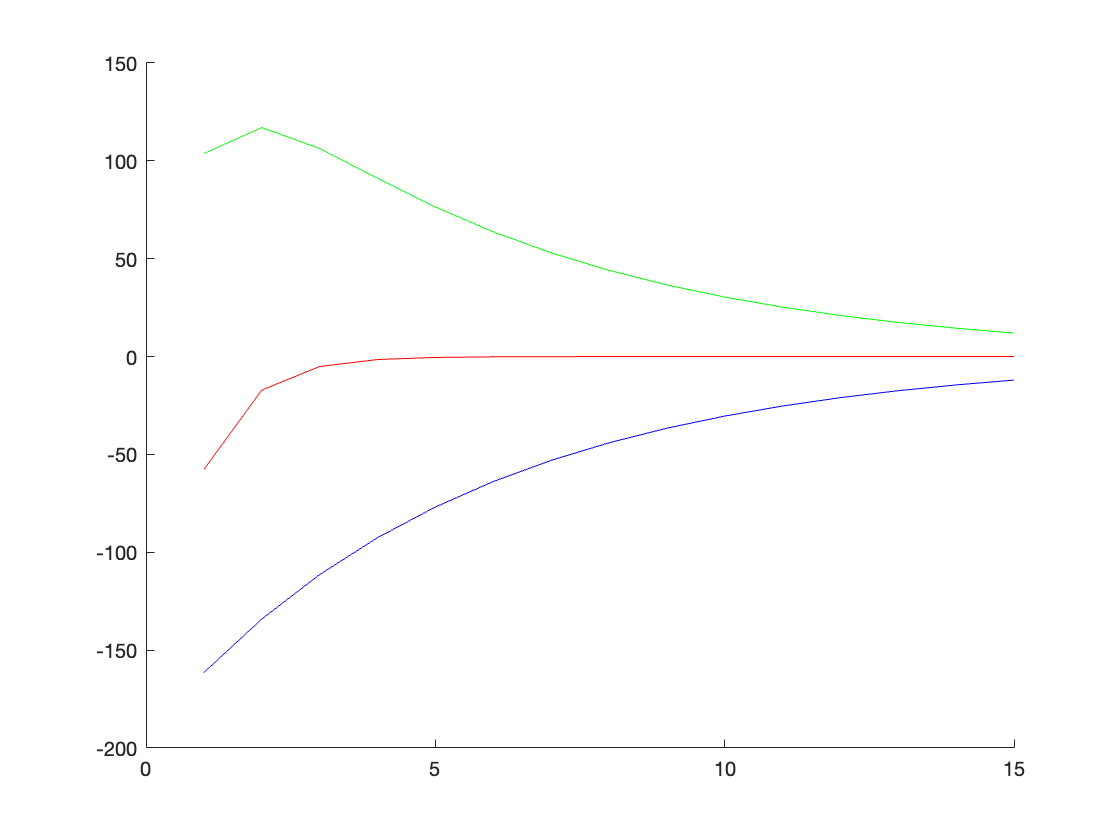

xsols=zeros(2, 15);
xsols_norm=zeros(1, 15);
coeff1=zeros(1, 15);
coeff2=zeros(1, 15);
for i=1:1:15
    coeffs=exp(lambda_vec*i).*a_const;
    coeff1(1,i)=coeffs(1,1);
    coeff2(1,i)=coeffs(1,2);
    % sum(,2) sums each of the rows
    xsols(:, i) = sum([coeffs;coeffs].*e_vecs, 2).';
    % typo in pset according to OH since norm is sqrt
    xsols_norm(1, i)=sqrt(xsols(1, i).^2 + (xsols(2, i).^2));
end

figure
hold on
t=1:1:15;
plot(t, xsols_norm, 'g')
plot(t, coeff1, 'r')
plot(t, coeff2, 'b')
hold off

Because the eigenvectors are close to parallel, there is some initial oscillation and the green goes up for a bit, but eventually goes towards 0 since the eigenvalues are still negative.

## 3

3a)

A=[5, -1, -1; 
    -10, 5, 3; 
    16, -2, -1];


TF during OH said I can use the eig() function directly here

[V, D] = eig(A)

V =   -0.1374 - 0.0000i  -0.1374 + 0.0000i  -0.1374 + 0.0000i
   0.5494 + 0.0000i   0.5494 - 0.0000i   0.5494 + 0.0000i
  -0.8242 + 0.0000i  -0.8242 + 0.0000i  -0.8242 + 0.0000i


D =    3.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 0.0000i



disp('det(V):')

det(V):


disp(det(V))

  -9.5745e-23 - 1.1290e-16i



No, we can't directly diagonalize A. Literally all of our eigenvalues are 3/our eigenvectors are the same, so we don't have enough distinct eigenvectors. This is reflected by the determinant which is basically zero here so V isn't invertible.

disp('M and J from A:')

M and J from A:


[M,J]=jordan(A)

M =     -2     2     1
     8   -10     0
   -12    16     0


J =      3     1     0
     0     3     1
     0     0     3


3b)

A1=A+[0 0 0.0000001; 0 0 0; 0 0 0];

disp('M and J from A1:')

M and J from A1:


[V, D] = eig(A1)

V =    0.1369 + 0.0000i  -0.1376 - 0.0004i  -0.1376 + 0.0004i
  -0.5491 + 0.0000i   0.5496 + 0.0004i   0.5496 - 0.0004i
   0.8244 + 0.0000i  -0.8240 + 0.0000i  -0.8240 + 0.0000i


D =    2.9893 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0053 + 0.0092i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0053 - 0.0092i


The Jordan form is very sensitive to noise. As we can see, when adding noise, the new eigenvectors and values will change and can quickly start to differ from each other, allowing a matrix to become diagonalizable.

3c)

So we start with eigenvalue 3

lambda=3;
I = eye(3);        
B = A - (lambda*I);
B(abs(B)<1.e-13)=0;

B3 = B^3;
B3(abs(B3)<1.e-13)=0;
B3null=null(B3)

B3null =      1     0     0
     0     1     0
     0     0     1


v3=B3null(:, 1);

v2=B*v3

v2 =      2
   -10
    16


v1=B*v2

v1 =     -2
     8
   -12



disp('M matrix found using generalized eigenvectors:')

M matrix found using generalized eigenvectors:


M=[v1 v2 v3]

M =     -2     2     1
     8   -10     0
   -12    16     0


3d)

disp('J matrix:')

J matrix:


J=inv(M)*A*M

J =     3.0000    1.0000         0
    0.0000    3.0000    1.0000
    0.0000   -0.0000    3.0000



disp('Matlab calculated M and J from jordan():')

Matlab calculated M and J from jordan():


[M,J]=jordan(A)

M =     -2     2     1
     8   -10     0
   -12    16     0


J =      3     1     0
     0     3     1
     0     0     3


The M and J matrices found using generalized eigenvectors are indeed equal to the ones calculated from Matlab's jordan() function.